% Step 1
% Mean Gaussian = 0
% Variance Gaussian = sigma^2

mu = 0;
sigma = sqrt(2);
M = 10000;

data = normrnd(mu, sigma, 1, M);

disp('Random Gaussian Distribution:');

Random Gaussian Distribution:


disp(data);

  Columns 1 through 3,276

   -2.1974   -0.5010    0.6141   -0.1435    2.8691   -0.5193   -3.3429    1.0322   -1.9785    1.8595    0.5711   -0.4867   -1.3860    2.6267    0.4378   -0.6917   -0.9827   -0.2551    1.7767    2.7022    0.0385    0.6041    0.4573   -2.3320    0.1985   -0.7043   -0.6050   -0.2134   -4.0882   -1.0388    1.0694    0.1708   -0.7296   -0.4820   -1.5273   -0.9863   -0.8245   -0.2632    0.8315   -0.0298   -0.1128   -1.1816    1.3840    0.3330    0.8005    0.3101    1.1423    2.1390   -0.6104    0.7673    0.9607   -0.0124    2.7039   -1.3840   -0.6875    0.1102    0.0371   -0.3151   -0.6784    1.1661   -0.0854   -1.1409    2.4223    1.2900    2.1055   -0.0378    2.7094    1.3006   -2.5570   -1.7894    0.8254   -0.1643   -0.2034    1.5200    2.4073    0.5533    0.1801    3.1833   -0.0151   -0.6372   -0.8415   -1.0404    0.1155   -1.2174   -2.6282   -1.8171    0.6169    1.5433    1.7007    3.2709   -1.5330    1.9297    0.1155   -0.6615   -0.6030    1.2581    0.9189   

% Step 2

mu_s = mean(data);      % Sample Mean of Data
sigma_s = std(data);    % Sample Standard Deviation of Data

disp(['Sample Mean: ', num2str(mu_s)]);

Sample Mean: -0.014813


disp(['Sample Standard Deviation: ', num2str(sigma_s)]);

Sample Standard Deviation: 1.3871


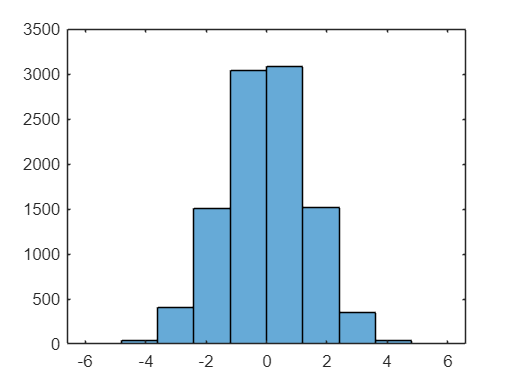

% Step 3

K = 10;
h = histogram(data, K);

mj = h.Values;                                  % # Samples In Each Bin
Cj = h.BinEdges(1:end-1) + diff(h.BinEdges)/2;  % Centers Of Each Bin (From Documentation)

disp('Bin Samples (mj):');

Bin Samples (mj):


disp(mj);

           4          39         402        1508        3044        3087        1520         353          40           3



disp('Bin Centers (Cj):');

Bin Centers (Cj):


disp(Cj);

   -5.4000   -4.2000   -3.0000   -1.8000   -0.6000    0.6000    1.8000    3.0000    4.2000    5.4000



% Step 4

Delta = (Cj(end) - Cj(1)) / (K - 1);    % (End Bin - Start Bin) / # Gaps

disp(['Bin Length Delta: ', num2str(Delta)]);

Bin Length Delta: 1.2


% Step 5

simulated_pdf = mj / (M * Delta);   % Directly From Lab Procedure

disp('Simulated pdf at Bin Centers:');

Simulated pdf at Bin Centers:


disp(simulated_pdf);

    0.0003    0.0032    0.0335    0.1257    0.2537    0.2572    0.1267    0.0294    0.0033    0.0002



% Step 6

numerator = -((Cj - mu_s).^2);          % Numerator
denominator = 2 * sigma_s^2;            % Denominator
scalar = 1 / (sigma_s * sqrt(2*pi));    % Scalar / Front Value?

theoretical_pdf = scalar * exp(numerator / denominator);

disp('Theoretical pdf at Bin Centers:');

Theoretical pdf at Bin Centers:


disp(simulated_pdf);

    0.0003    0.0032    0.0335    0.1257    0.2537    0.2572    0.1267    0.0294    0.0033    0.0002



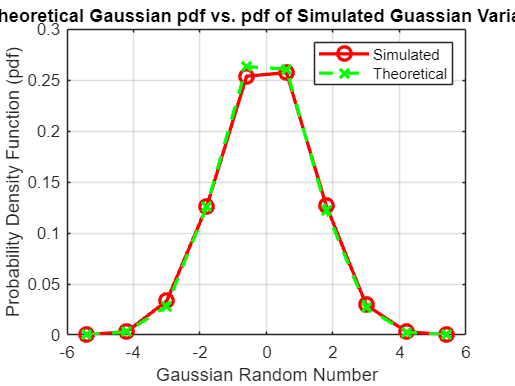

% Step 7

figure;
plot(Cj, simulated_pdf, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

plot(Cj, theoretical_pdf, 'g-x', 'LineStyle', '--', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Gaussian Random Number');
ylabel('Probability Density Function (pdf)');
title('Theoretical Gaussian pdf vs. pdf of Simulated Guassian Variates');
legend('Simulated', 'Theoretical');

grid on;
hold off;